# Canny Edge Detection

**Author: Chul Min Yeum**

**Email: cmyeum@uwaterloo.ca**

Last updated: 2018-12-12

### Effect of Gaussian Kernel Sizes

clear; close all; clc;

img = imread('westconcordaerial.png');

f1 =  fspecial('gaussian', 101,1);
f2 =  fspecial('gaussian', 101,5);
f3 =  fspecial('gaussian', 101,10);

img_f1 = imfilter(img, f1);
img_f2 = imfilter(img, f2);
img_f3 = imfilter(img, f3);

fig1 = figure(1);
subplot(241); imshow(img);
subplot(242); imshow(img_f1);
subplot(243); imshow(img_f2);
subplot(244); imshow(img_f3);


BW_filt = edge(rgb2gray(img), 'Canny');
BW_filt_f1 = edge(rgb2gray(img_f1), 'Canny');
BW_filt_f2 = edge(rgb2gray(img_f2), 'Canny');
BW_filt_f3 = edge(rgb2gray(img_f3), 'Canny');

subplot(245); imshow(BW_filt);
subplot(246); imshow(BW_filt_f1);
subplot(247); imshow(BW_filt_f2);
subplot(248); imshow(BW_filt_f3);
set(fig1,'Position', [100 100 800 600]);

### Effect of High and Low Threshold

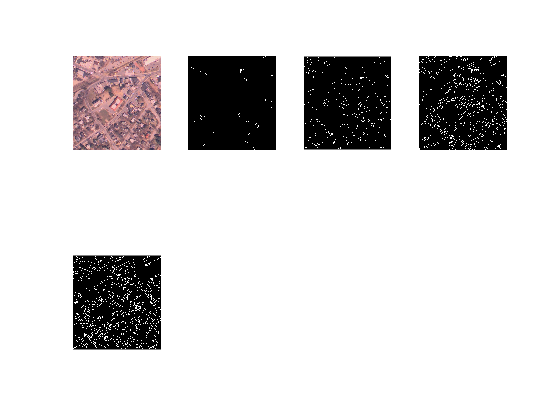

clear; close all; clc;

img = imread('westconcordaerial.png');

f = fspecial('gaussian', 3);
img_f = imfilter(img, f);

fig1 = figure(1);
subplot(241); imshow(img_f);

BW_filt = edge(rgb2gray(img_f), 'Canny', [0.4 0.8]);
subplot(242); imshow(BW_filt);

BW_filt = edge(rgb2gray(img_f), 'Canny', [0.4 0.5]);
subplot(243); imshow(BW_filt);

BW_filt = edge(rgb2gray(img_f), 'Canny', [0.2 0.5]);
subplot(244); imshow(BW_filt);

BW_filt = edge(rgb2gray(img_f), 'Canny', [0.1 0.5]);
subplot(245); imshow(BW_filt);

### Beam

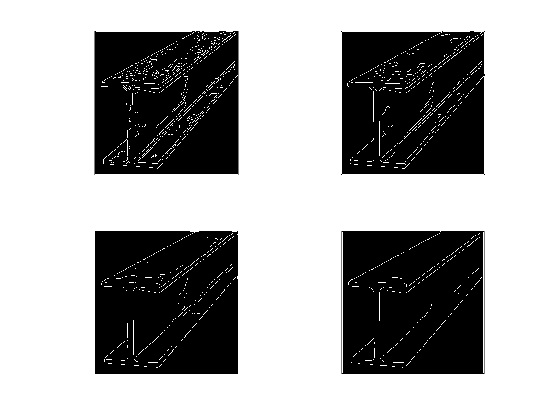

clear; close all; clc;

img = imread('beam.jpg');

f = fspecial('gaussian', 6,1);
img_f1 = imfilter(img, f);
BW_filt1 = edge(rgb2gray(img_f1), 'Canny');

f = fspecial('gaussian', 13,2);
img_f2 = imfilter(img, f);
BW_filt2 = edge(rgb2gray(img_f2), 'Canny');

f = fspecial('gaussian', 19,3);
img_f3 = imfilter(img, f);
BW_filt3 = edge(rgb2gray(img_f3), 'Canny');

f = fspecial('gaussian', 25,4);
img_f4 = imfilter(img, f);
BW_filt4 = edge(rgb2gray(img_f4), 'Canny');

figure(1);
subplot(221); imshow(BW_filt1)
subplot(222); imshow(BW_filt2)
subplot(223); imshow(BW_filt3)
subplot(224); imshow(BW_filt4)